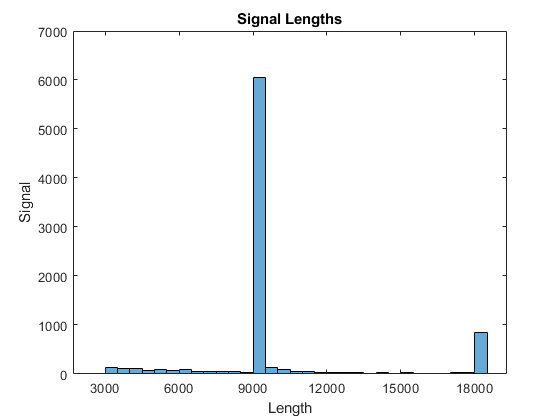

%discovering data
L = cellfun(@length, Signals);
h = histogram(L);
xticks(0:3000:18000);
xticklabels(0:3000:18000);
title('Signal Lengths')
xlabel('Length')
ylabel('Signal')

%consider only AFib, Normal, and Other
A = Labels(Labels == 'A');
ASig = Signals(Labels == 'A');
N = Labels(Labels == 'N');
NSig = Signals(Labels == 'N');
O = Labels(Labels == 'O');
OSig = Signals(Labels == 'O');

%check the balance of data
Labels = vertcat(A, N, O);
Labels = removecats(Labels);
Signals = vertcat(ASig, NSig, OSig);
summary(Labels);

     A       738 
     N      5050 
     O      2456 


%standard length 9000s, segment long signal and remove short signals
Labels = cellstr(Labels);
[data, labels] = SegmentSignals(Signals, Labels, 4500);
Labels = categorical(labels);
summary(Labels);

     A       1494 
     N      10327 
     O       5417 


%divide training and testing set
A = Labels(Labels == 'A');
ASig = data(Labels == 'A');
N = Labels(Labels == 'N');
NSig = data(Labels == 'N');
O = Labels(Labels == 'O');
OSig = data(Labels == 'O');

[trainIndA,~,testIndA] = dividerand(length(A),0.9,0.0,0.1);
[trainIndN,~,testIndN] = dividerand(length(N),0.9,0.0,0.1);
[trainIndO,~,testIndO] = dividerand(length(O),0.9,0.0,0.1);

XTrainA = ASig(trainIndA);
YTrainA = A(trainIndA);

XTrainN = NSig(trainIndN);
YTrainN = N(trainIndN);

XTrainO = OSig(trainIndO);
YTrainO = O(trainIndO);

XTestA = ASig(testIndA);
YTestA = A(testIndA);

XTestN = NSig(testIndN);
YTestN = N(testIndN);

XTestO = OSig(testIndO);
YTestO = O(testIndO);

%data augmentation, each labels will have 1000 signals for trainning and
%100 signals for testing
% TrainAS = repmat(XTrainA, 2, 1);
% TrainAL = repmat(YTrainA, 2, 1);
% TestAS = repmat(XTestA, 2, 1);
% TestAL = repmat(YTestA, 2, 1);

XTrain = [XTrainN(1:length(YTrainA)); XTrainA(:); XTrainO(1:length(YTrainA))];
YTrain = [YTrainN(1:length(YTrainA)); YTrainA(:); YTrainO(1:length(YTrainA))];

XTest = [XTestN(1:length(YTestA)); XTestA(:); XTestO(1:length(YTestA))];
YTest = [YTestN(1:length(YTestA)); YTestA(:); YTestO(1:length(YTestA))];

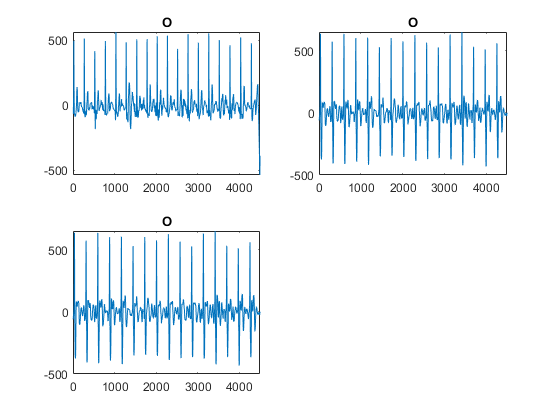

%plot example data
figure(1)
subplot(2,2,1)
plot(XTrain{end,:}); title(YTrain(end));
subplot(2,2,2)
plot(XTrain{end-1,:}); title(YTrain(end-1));
subplot(2,2,3)
plot(XTrain{end-2,:}); title(YTrain(end-2));

% %filter the signals to remove baseline noise
% %test filter
% hpFilt = designfilt('highpassiir','FilterOrder',8, ...
%          'PassbandFrequency',1,'PassbandRipple',0.2, ...
%          'SampleRate',300);
% sig1 = filtfilt(hpFilt,XTrain{1,:});
% sig2 = filtfilt(hpFilt,XTrain{1001,:});
% sig3 = filtfilt(hpFilt,XTrain{2001,:});
% figure(2)
% subplot(2,2,1)
% plot(sig1); title(YTrain(1));
% subplot(2,2,2)
% plot(sig2); title(YTrain(1001));
% subplot(2,2,3)
% plot(sig3); title(YTrain(2001));

% %filter all signals
% hpFilt = designfilt('highpassiir','FilterOrder',8, ...
%          'PassbandFrequency',0.75,'PassbandRipple',0.2, ...
%          'SampleRate',300);
% XXTrain = cellfun(@(x)filtfilt(hpFilt,x),XTrain,'UniformOutput',false);
% XXTest =  cellfun(@(x)filtfilt(hpFilt,x),XTest,'UniformOutput',false);

% 
% figure(3)
% subplot(2,2,1)
% plot(XXTrain{1,:}); title(YTrain(1));
% subplot(2,2,2)
% plot(XXTrain{1001,:}); title(YTrain(1001));
% subplot(2,2,3)
% plot(XXTrain{2001,:}); title(YTrain(2001));

%prepare data
Labels = YTrain;
Signals = XTrain;
Data = cell2mat(Signals);
ECGData = struct();
ECGData.Labels = Labels;
ECGData.Data = Data;

Labels = YTest;
Signals = XTest;
Data = cell2mat(Signals);
ECGDataTest = struct();
ECGDataTest.Labels = Labels;
ECGDataTest.Data = Data;

%Use GoogLeNet
parentDir = '\\uofa\users$\users0\a1798520\MATLAB\CNNs\Training1509';
dataDir = 'data';
helperCreateECGDirectories(ECGData,parentDir,dataDir)

%Generating scalograms
helperCreateRGBfromTF(ECGData,parentDir,dataDir)
%store images
allImages = imageDatastore(fullfile(parentDir,dataDir),...
     'IncludeSubfolders',true,...
    'LabelSource','foldernames');
%training vs validating sets
rng default
[imgsTrain,imgsValidation] = splitEachLabel(allImages,0.8,'randomized');
disp(['Number of training images: ',num2str(numel(imgsTrain.Files))]);

Number of training images: 3228


disp(['Number of validation images: ',num2str(numel(imgsValidation.Files))]);

Number of validation images: 807


%  net = googlenet;

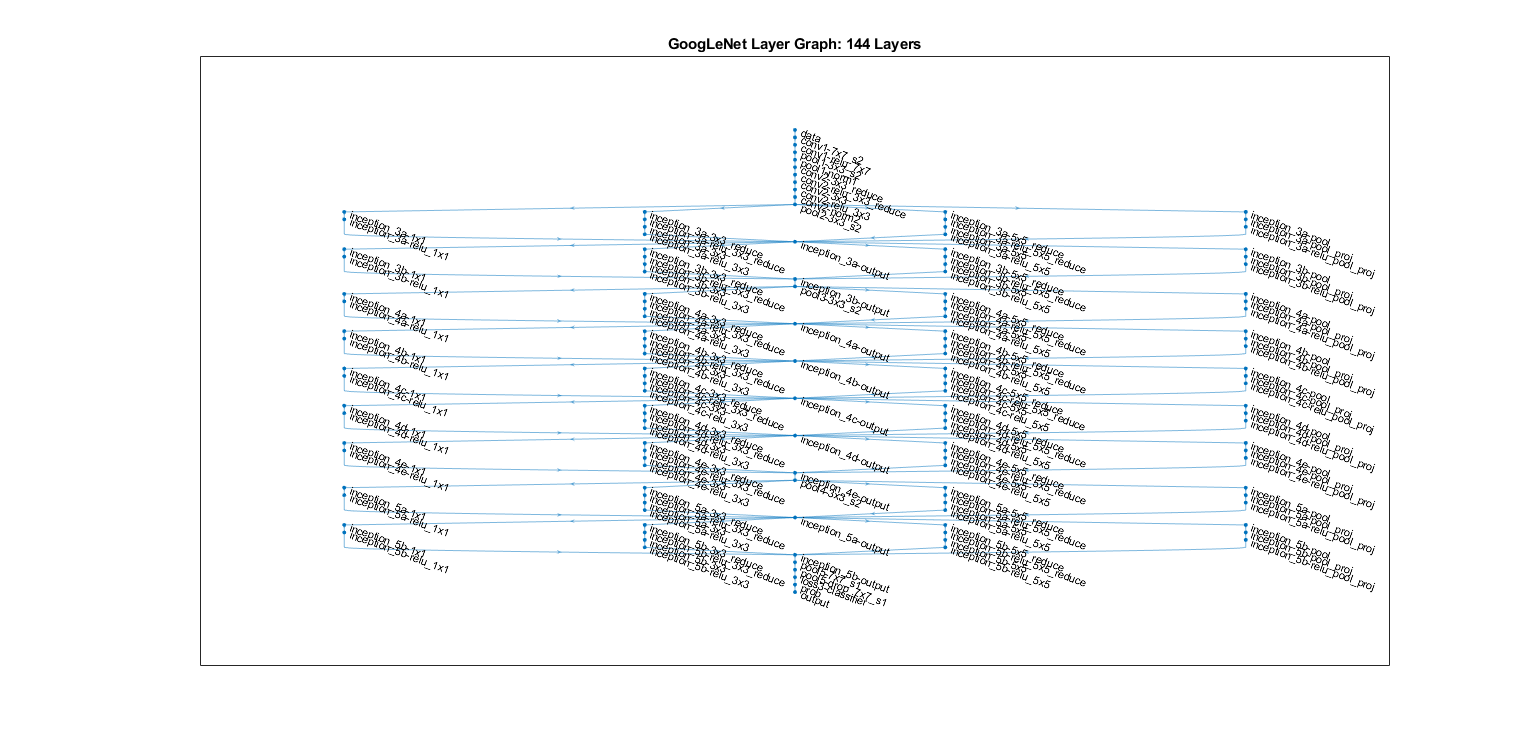

Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:15 |       40.00% |       33.33% |       3.3053 |       2.0170 |      1.0000e-04 |


|       1 |          10 |       00:00:23 |       20.00% |       30.86% |       2.1768 |       1.2344 |      1.0000e-04 |


|       1 |          20 |       00:00:30 |       40.00% |       46.34% |       1.4529 |       1.0680 |      1.0000e-04 |


|       1 |          30 |       00:00:36 |       40.00% |       51.30% |       1.8750 |       1.0589 |      1.0000e-04 |


|       1 |          40 |       00:00:43 |       60.00% |       45.85% |       1.3990 |       1.1094 |      1.0000e-04 |


|       1 |          50 |       00:00:50 |       40.00% |       54.40% |       1.1589 |       0.9862 |      1.0000e-04 |


|       1 |          60 |       00:00:57 |       40.00% |       55.76% |       1.3049 |       0.9295 |      1.0000e-04 |


|       1 |          70 |       00:01:04 |       70.00% |       58.86% |       0.7488 |       0.8573 |      1.0000e-04 |


|       1 |          80 |       00:01:11 |       60.00% |       60.35% |       0.8290 |       0.8684 |      1.0000e-04 |


|       1 |          90 |       00:01:17 |       70.00% |       59.85% |       0.8380 |       0.8407 |      1.0000e-04 |


|       1 |         100 |       00:01:24 |       80.00% |       58.61% |       0.6459 |       0.8482 |      1.0000e-04 |


|       1 |         110 |       00:01:31 |       30.00% |       61.96% |       1.0211 |       0.8225 |      1.0000e-04 |


|       1 |         120 |       00:01:38 |       80.00% |       56.88% |       0.7192 |       0.8276 |      1.0000e-04 |


|       1 |         130 |       00:01:45 |       40.00% |       62.08% |       1.4445 |       0.8110 |      1.0000e-04 |


|       1 |         140 |       00:01:52 |       70.00% |       61.71% |       0.8313 |       0.8317 |      1.0000e-04 |


|       1 |         150 |       00:01:58 |       50.00% |       60.10% |       0.9804 |       0.8294 |      1.0000e-04 |


|       1 |         160 |       00:02:05 |      100.00% |       62.45% |       0.5318 |       0.7849 |      1.0000e-04 |


|       1 |         170 |       00:02:12 |       60.00% |       62.83% |       0.7551 |       0.8168 |      1.0000e-04 |


|       1 |         180 |       00:02:19 |       80.00% |       61.96% |       0.7390 |       0.8018 |      1.0000e-04 |


|       1 |         190 |       00:02:25 |       80.00% |       64.31% |       0.7790 |       0.7673 |      1.0000e-04 |


|       1 |         200 |       00:02:32 |       70.00% |       64.81% |       0.7998 |       0.7778 |      1.0000e-04 |


|       1 |         210 |       00:02:39 |       60.00% |       65.80% |       0.9890 |       0.7544 |      1.0000e-04 |


|       1 |         220 |       00:02:45 |       50.00% |       64.93% |       0.8928 |       0.7629 |      1.0000e-04 |


|       1 |         230 |       00:02:52 |       40.00% |       65.18% |       0.9323 |       0.7477 |      1.0000e-04 |


|       1 |         240 |       00:02:58 |       60.00% |       65.30% |       0.7133 |       0.7525 |      1.0000e-04 |


|       1 |         250 |       00:03:05 |       50.00% |       65.92% |       0.9510 |       0.7570 |      1.0000e-04 |


|       1 |         260 |       00:03:12 |       50.00% |       64.44% |       0.9695 |       0.7566 |      1.0000e-04 |


|       1 |         270 |       00:03:19 |       70.00% |       64.44% |       0.6436 |       0.7656 |      1.0000e-04 |


|       1 |         280 |       00:03:25 |       40.00% |       66.91% |       1.0543 |       0.7408 |      1.0000e-04 |


|       1 |         290 |       00:03:32 |       60.00% |       67.66% |       0.6936 |       0.7317 |      1.0000e-04 |


|       1 |         300 |       00:03:39 |       50.00% |       68.28% |       0.9438 |       0.7263 |      1.0000e-04 |


|       1 |         310 |       00:03:45 |       60.00% |       66.67% |       0.8324 |       0.7354 |      1.0000e-04 |


|       1 |         320 |       00:03:52 |       90.00% |       68.40% |       0.7446 |       0.7213 |      1.0000e-04 |


|       2 |         330 |       00:03:59 |       50.00% |       66.67% |       0.7639 |       0.7159 |      1.0000e-04 |


|       2 |         340 |       00:04:05 |       40.00% |       68.40% |       0.9715 |       0.7050 |      1.0000e-04 |


|       2 |         350 |       00:04:12 |       60.00% |       67.04% |       0.8846 |       0.7142 |      1.0000e-04 |


|       2 |         360 |       00:04:19 |       60.00% |       66.79% |       0.7097 |       0.7193 |      1.0000e-04 |


|       2 |         370 |       00:04:25 |       80.00% |       66.91% |       0.6366 |       0.7128 |      1.0000e-04 |


|       2 |         380 |       00:04:32 |       60.00% |       66.79% |       0.9236 |       0.7340 |      1.0000e-04 |


|       2 |         390 |       00:04:39 |       50.00% |       67.53% |       0.6418 |       0.7025 |      1.0000e-04 |


|       2 |         400 |       00:04:46 |       60.00% |       68.03% |       0.6943 |       0.7038 |      1.0000e-04 |


|       2 |         410 |       00:04:52 |       70.00% |       69.14% |       0.5991 |       0.6925 |      1.0000e-04 |


|       2 |         420 |       00:04:59 |       90.00% |       68.77% |       0.4268 |       0.6825 |      1.0000e-04 |


|       2 |         430 |       00:05:05 |       60.00% |       68.40% |       0.8797 |       0.6971 |      1.0000e-04 |


|       2 |         440 |       00:05:12 |       80.00% |       66.79% |       0.4888 |       0.7073 |      1.0000e-04 |


|       2 |         450 |       00:05:19 |       60.00% |       69.02% |       0.6122 |       0.6915 |      1.0000e-04 |


|       2 |         460 |       00:05:26 |       70.00% |       66.29% |       0.6942 |       0.7610 |      1.0000e-04 |


|       2 |         470 |       00:05:32 |       70.00% |       67.41% |       0.6473 |       0.7286 |      1.0000e-04 |


|       2 |         480 |       00:05:39 |       40.00% |       69.89% |       1.2579 |       0.6772 |      1.0000e-04 |


|       2 |         490 |       00:05:45 |       50.00% |       67.41% |       1.1639 |       0.7562 |      1.0000e-04 |


|       2 |         500 |       00:05:52 |       60.00% |       68.03% |       1.1539 |       0.7253 |      1.0000e-04 |


|       2 |         510 |       00:05:58 |       40.00% |       67.91% |       1.0937 |       0.6724 |      1.0000e-04 |


|       2 |         520 |       00:06:05 |      100.00% |       68.15% |       0.4527 |       0.6938 |      1.0000e-04 |


|       2 |         530 |       00:06:12 |       50.00% |       69.14% |       0.7458 |       0.6639 |      1.0000e-04 |


|       2 |         540 |       00:06:19 |       90.00% |       68.15% |       0.7176 |       0.7127 |      1.0000e-04 |


|       2 |         550 |       00:06:26 |       60.00% |       69.52% |       0.8576 |       0.6632 |      1.0000e-04 |


|       2 |         560 |       00:06:32 |      100.00% |       70.14% |       0.2667 |       0.6707 |      1.0000e-04 |


|       2 |         570 |       00:06:39 |       60.00% |       70.01% |       1.2955 |       0.6626 |      1.0000e-04 |


|       2 |         580 |       00:06:45 |       90.00% |       69.14% |       0.3877 |       0.6817 |      1.0000e-04 |


|       2 |         590 |       00:06:52 |       60.00% |       70.88% |       0.7463 |       0.6578 |      1.0000e-04 |


|       2 |         600 |       00:06:59 |       70.00% |       68.90% |       0.6339 |       0.6896 |      1.0000e-04 |


|       2 |         610 |       00:07:05 |       70.00% |       71.13% |       0.6800 |       0.6581 |      1.0000e-04 |


|       2 |         620 |       00:07:12 |       60.00% |       71.50% |       0.7124 |       0.6569 |      1.0000e-04 |


|       2 |         630 |       00:07:19 |       70.00% |       72.24% |       0.7318 |       0.6554 |      1.0000e-04 |


|       2 |         640 |       00:07:26 |       60.00% |       70.26% |       0.7183 |       0.6485 |      1.0000e-04 |


|       3 |         650 |       00:07:32 |       80.00% |       69.39% |       0.6407 |       0.6638 |      1.0000e-04 |


|       3 |         660 |       00:07:39 |       60.00% |       71.25% |       0.8663 |       0.6438 |      1.0000e-04 |


|       3 |         670 |       00:07:46 |       70.00% |       70.88% |       0.7064 |       0.6421 |      1.0000e-04 |


|       3 |         680 |       00:07:52 |       80.00% |       69.89% |       0.5917 |       0.6610 |      1.0000e-04 |


|       3 |         690 |       00:07:59 |       80.00% |       70.63% |       0.6981 |       0.6553 |      1.0000e-04 |


|       3 |         700 |       00:08:06 |       70.00% |       69.14% |       0.5937 |       0.6774 |      1.0000e-04 |


|       3 |         710 |       00:08:12 |       70.00% |       69.89% |       0.6983 |       0.6641 |      1.0000e-04 |


|       3 |         720 |       00:08:19 |       90.00% |       71.38% |       0.4132 |       0.6409 |      1.0000e-04 |


|       3 |         730 |       00:08:26 |       80.00% |       71.75% |       0.3236 |       0.6347 |      1.0000e-04 |


|       3 |         740 |       00:08:33 |       70.00% |       69.76% |       0.5291 |       0.6547 |      1.0000e-04 |


|       3 |         750 |       00:08:39 |       70.00% |       70.38% |       0.6295 |       0.6364 |      1.0000e-04 |


|       3 |         760 |       00:08:46 |       70.00% |       70.38% |       0.5450 |       0.6437 |      1.0000e-04 |


|       3 |         770 |       00:08:52 |       80.00% |       71.38% |       0.4901 |       0.6381 |      1.0000e-04 |


|       3 |         780 |       00:08:59 |       80.00% |       70.63% |       0.6338 |       0.6733 |      1.0000e-04 |


|       3 |         790 |       00:09:06 |       70.00% |       69.76% |       0.4336 |       0.6914 |      1.0000e-04 |


|       3 |         800 |       00:09:13 |       80.00% |       71.75% |       0.5574 |       0.6426 |      1.0000e-04 |


|       3 |         810 |       00:09:19 |       90.00% |       65.06% |       0.4935 |       0.8267 |      1.0000e-04 |


|       3 |         820 |       00:09:26 |       90.00% |       69.76% |       0.3201 |       0.6786 |      1.0000e-04 |


|       3 |         830 |       00:09:33 |       70.00% |       70.88% |       0.7297 |       0.6483 |      1.0000e-04 |


|       3 |         840 |       00:09:39 |       80.00% |       68.90% |       0.4130 |       0.6573 |      1.0000e-04 |


|       3 |         850 |       00:09:46 |      100.00% |       72.49% |       0.3956 |       0.6209 |      1.0000e-04 |


|       3 |         860 |       00:09:53 |       80.00% |       71.38% |       0.7874 |       0.6428 |      1.0000e-04 |


|       3 |         870 |       00:10:00 |       80.00% |       72.24% |       0.6151 |       0.6265 |      1.0000e-04 |


|       3 |         880 |       00:10:06 |       90.00% |       72.61% |       0.2385 |       0.6124 |      1.0000e-04 |


|       3 |         890 |       00:10:13 |       80.00% |       70.88% |       0.4895 |       0.6332 |      1.0000e-04 |


|       3 |         900 |       00:10:20 |       90.00% |       72.12% |       0.2731 |       0.6403 |      1.0000e-04 |


|       3 |         910 |       00:10:26 |       70.00% |       71.38% |       0.7569 |       0.6279 |      1.0000e-04 |


|       3 |         920 |       00:10:33 |       80.00% |       71.13% |       0.5915 |       0.6556 |      1.0000e-04 |


|       3 |         930 |       00:10:40 |       60.00% |       72.61% |       0.9747 |       0.6200 |      1.0000e-04 |


|       3 |         940 |       00:10:47 |       90.00% |       73.36% |       0.4994 |       0.6258 |      1.0000e-04 |


|       3 |         950 |       00:10:53 |       70.00% |       73.11% |       0.6330 |       0.6223 |      1.0000e-04 |


|       3 |         960 |       00:11:00 |       90.00% |       72.12% |       0.3150 |       0.6149 |      1.0000e-04 |


|       4 |         970 |       00:11:07 |       80.00% |       72.99% |       0.7925 |       0.5980 |      1.0000e-04 |


|       4 |         980 |       00:11:13 |       90.00% |       72.24% |       0.4435 |       0.6028 |      1.0000e-04 |


|       4 |         990 |       00:11:20 |       30.00% |       72.99% |       1.1287 |       0.6044 |      1.0000e-04 |


|       4 |        1000 |       00:11:27 |       70.00% |       71.38% |       0.6162 |       0.6324 |      1.0000e-04 |


|       4 |        1010 |       00:11:34 |      100.00% |       73.98% |       0.3006 |       0.5986 |      1.0000e-04 |


|       4 |        1020 |       00:11:41 |       70.00% |       72.61% |       0.4754 |       0.6336 |      1.0000e-04 |


|       4 |        1030 |       00:11:47 |       70.00% |       71.87% |       0.4896 |       0.6328 |      1.0000e-04 |


|       4 |        1040 |       00:11:54 |       30.00% |       73.23% |       1.1589 |       0.5956 |      1.0000e-04 |


|       4 |        1050 |       00:12:00 |       70.00% |       73.85% |       0.4529 |       0.5929 |      1.0000e-04 |


|       4 |        1060 |       00:12:07 |       50.00% |       73.11% |       0.7952 |       0.6142 |      1.0000e-04 |


|       4 |        1070 |       00:12:14 |       70.00% |       73.73% |       0.6449 |       0.5957 |      1.0000e-04 |


|       4 |        1080 |       00:12:21 |       70.00% |       73.73% |       0.7843 |       0.5924 |      1.0000e-04 |


|       4 |        1090 |       00:12:27 |       30.00% |       73.23% |       0.9496 |       0.5944 |      1.0000e-04 |


|       4 |        1100 |       00:12:34 |       70.00% |       74.23% |       0.4328 |       0.6000 |      1.0000e-04 |


|       4 |        1110 |       00:12:40 |      100.00% |       71.50% |       0.3061 |       0.6651 |      1.0000e-04 |


|       4 |        1120 |       00:12:47 |       80.00% |       72.49% |       0.5352 |       0.6176 |      1.0000e-04 |


|       4 |        1130 |       00:12:54 |       80.00% |       72.37% |       0.7660 |       0.6641 |      1.0000e-04 |


|       4 |        1140 |       00:13:00 |       70.00% |       72.61% |       0.5607 |       0.5906 |      1.0000e-04 |


|       4 |        1150 |       00:13:07 |       80.00% |       70.51% |       0.5659 |       0.6820 |      1.0000e-04 |


|       4 |        1160 |       00:13:14 |       40.00% |       72.37% |       0.7086 |       0.6201 |      1.0000e-04 |


|       4 |        1170 |       00:13:21 |       70.00% |       74.10% |       0.5268 |       0.5957 |      1.0000e-04 |


|       4 |        1180 |       00:13:27 |       80.00% |       71.13% |       0.5371 |       0.6447 |      1.0000e-04 |


|       4 |        1190 |       00:13:34 |       60.00% |       74.35% |       0.7409 |       0.5751 |      1.0000e-04 |


|       4 |        1200 |       00:13:41 |       70.00% |       74.23% |       0.5235 |       0.5784 |      1.0000e-04 |


|       4 |        1210 |       00:13:48 |       50.00% |       72.86% |       0.7260 |       0.6188 |      1.0000e-04 |


|       4 |        1220 |       00:13:54 |       90.00% |       73.61% |       0.7428 |       0.5940 |      1.0000e-04 |


|       4 |        1230 |       00:14:01 |       70.00% |       72.74% |       0.6359 |       0.6031 |      1.0000e-04 |


|       4 |        1240 |       00:14:08 |       70.00% |       72.61% |       0.4513 |       0.6182 |      1.0000e-04 |


|       4 |        1250 |       00:14:15 |       90.00% |       73.98% |       0.2790 |       0.5886 |      1.0000e-04 |


|       4 |        1260 |       00:14:22 |       80.00% |       73.85% |       0.5064 |       0.5843 |      1.0000e-04 |


|       4 |        1270 |       00:14:28 |       70.00% |       74.60% |       0.6565 |       0.5872 |      1.0000e-04 |


|       4 |        1280 |       00:14:35 |       80.00% |       73.98% |       0.7302 |       0.5799 |      1.0000e-04 |


|       5 |        1290 |       00:14:41 |       80.00% |       74.72% |       0.2587 |       0.5680 |      1.0000e-04 |


|       5 |        1300 |       00:14:48 |       80.00% |       74.72% |       0.5486 |       0.5826 |      1.0000e-04 |


|       5 |        1310 |       00:14:55 |       90.00% |       73.98% |       0.3927 |       0.6108 |      1.0000e-04 |


|       5 |        1320 |       00:15:01 |      100.00% |       74.85% |       0.1256 |       0.5872 |      1.0000e-04 |


|       5 |        1330 |       00:15:08 |       80.00% |       75.71% |       0.4027 |       0.5686 |      1.0000e-04 |


|       5 |        1340 |       00:15:15 |       90.00% |       74.10% |       0.2326 |       0.6154 |      1.0000e-04 |


|       5 |        1350 |       00:15:22 |       80.00% |       74.97% |       0.6160 |       0.5884 |      1.0000e-04 |


|       5 |        1360 |       00:15:29 |       90.00% |       75.22% |       0.3729 |       0.5748 |      1.0000e-04 |


|       5 |        1370 |       00:15:35 |       60.00% |       76.70% |       0.6944 |       0.5730 |      1.0000e-04 |


|       5 |        1380 |       00:15:42 |      100.00% |       75.09% |       0.2714 |       0.5877 |      1.0000e-04 |


|       5 |        1390 |       00:15:48 |      100.00% |       75.59% |       0.1772 |       0.5723 |      1.0000e-04 |


|       5 |        1400 |       00:15:55 |       70.00% |       75.09% |       0.6330 |       0.5873 |      1.0000e-04 |


|       5 |        1410 |       00:16:02 |       60.00% |       75.34% |       0.5584 |       0.5685 |      1.0000e-04 |


|       5 |        1420 |       00:16:08 |       90.00% |       74.60% |       0.2381 |       0.5693 |      1.0000e-04 |


|       5 |        1430 |       00:16:15 |      100.00% |       72.86% |       0.2137 |       0.6525 |      1.0000e-04 |


|       5 |        1440 |       00:16:22 |       80.00% |       73.48% |       0.4586 |       0.5807 |      1.0000e-04 |


|       5 |        1450 |       00:16:29 |       70.00% |       75.71% |       0.5052 |       0.6103 |      1.0000e-04 |


|       5 |        1460 |       00:16:35 |       90.00% |       74.97% |       0.1864 |       0.5707 |      1.0000e-04 |


|       5 |        1470 |       00:16:42 |       70.00% |       70.01% |       0.7340 |       0.7431 |      1.0000e-04 |


|       5 |        1480 |       00:16:49 |       30.00% |       74.60% |       1.0472 |       0.5854 |      1.0000e-04 |


|       5 |        1490 |       00:16:56 |       80.00% |       75.84% |       0.3979 |       0.5674 |      1.0000e-04 |


|       5 |        1500 |       00:17:02 |       90.00% |       75.09% |       0.3709 |       0.5661 |      1.0000e-04 |


|       5 |        1510 |       00:17:09 |       80.00% |       74.72% |       0.4822 |       0.5833 |      1.0000e-04 |


|       5 |        1520 |       00:17:16 |       70.00% |       74.60% |       0.6601 |       0.5762 |      1.0000e-04 |


|       5 |        1530 |       00:17:23 |       80.00% |       75.34% |       0.4750 |       0.5674 |      1.0000e-04 |


|       5 |        1540 |       00:17:30 |       70.00% |       75.46% |       0.7900 |       0.5767 |      1.0000e-04 |


|       5 |        1550 |       00:17:36 |       90.00% |       75.84% |       0.6662 |       0.5495 |      1.0000e-04 |


|       5 |        1560 |       00:17:43 |      100.00% |       76.33% |       0.2108 |       0.5890 |      1.0000e-04 |


|       5 |        1570 |       00:17:50 |       90.00% |       76.58% |       0.3880 |       0.5420 |      1.0000e-04 |


|       5 |        1580 |       00:17:56 |       80.00% |       76.95% |       0.3778 |       0.5474 |      1.0000e-04 |


|       5 |        1590 |       00:18:03 |      100.00% |       76.70% |       0.2651 |       0.5514 |      1.0000e-04 |


|       5 |        1600 |       00:18:10 |       90.00% |       74.85% |       0.3242 |       0.6297 |      1.0000e-04 |


|       5 |        1610 |       00:18:17 |       80.00% |       76.70% |       0.4809 |       0.5438 |      1.0000e-04 |


|       6 |        1620 |       00:18:24 |       70.00% |       76.83% |       0.6038 |       0.5448 |      1.0000e-04 |


|       6 |        1630 |       00:18:30 |       70.00% |       74.23% |       0.8637 |       0.6058 |      1.0000e-04 |


|       6 |        1640 |       00:18:37 |       90.00% |       75.34% |       0.2925 |       0.5836 |      1.0000e-04 |


|       6 |        1650 |       00:18:43 |       60.00% |       77.82% |       1.0860 |       0.5418 |      1.0000e-04 |


|       6 |        1660 |       00:18:50 |       70.00% |       76.58% |       0.4488 |       0.5605 |      1.0000e-04 |


|       6 |        1670 |       00:18:57 |       70.00% |       75.46% |       0.6267 |       0.5856 |      1.0000e-04 |


|       6 |        1680 |       00:19:03 |      100.00% |       77.45% |       0.2858 |       0.5503 |      1.0000e-04 |


|       6 |        1690 |       00:19:10 |       80.00% |       75.84% |       0.5650 |       0.5674 |      1.0000e-04 |


|       6 |        1700 |       00:19:17 |      100.00% |       75.96% |       0.2037 |       0.5726 |      1.0000e-04 |


|       6 |        1710 |       00:19:23 |       80.00% |       77.08% |       0.3408 |       0.5868 |      1.0000e-04 |


|       6 |        1720 |       00:19:30 |       60.00% |       73.36% |       0.9086 |       0.6440 |      1.0000e-04 |


|       6 |        1730 |       00:19:37 |       80.00% |       73.73% |       0.4367 |       0.6013 |      1.0000e-04 |


|       6 |        1740 |       00:19:43 |       60.00% |       74.60% |       0.8168 |       0.5962 |      1.0000e-04 |


|       6 |        1750 |       00:19:50 |      100.00% |       76.08% |       0.1754 |       0.6079 |      1.0000e-04 |


|       6 |        1760 |       00:19:57 |       80.00% |       76.46% |       0.3283 |       0.5706 |      1.0000e-04 |


|       6 |        1770 |       00:20:04 |       90.00% |       77.45% |       0.1425 |       0.5431 |      1.0000e-04 |


|       6 |        1780 |       00:20:11 |       80.00% |       75.22% |       0.3866 |       0.6342 |      1.0000e-04 |


|       6 |        1790 |       00:20:18 |       80.00% |       72.00% |       0.5209 |       0.6962 |      1.0000e-04 |


|       6 |        1800 |       00:20:25 |       90.00% |       75.71% |       0.4625 |       0.5565 |      1.0000e-04 |


|       6 |        1810 |       00:20:31 |       70.00% |       76.70% |       0.4974 |       0.5724 |      1.0000e-04 |


|       6 |        1820 |       00:20:38 |       80.00% |       77.20% |       0.6045 |       0.5380 |      1.0000e-04 |


|       6 |        1830 |       00:20:45 |       60.00% |       75.59% |       0.6259 |       0.6040 |      1.0000e-04 |


|       6 |        1840 |       00:20:51 |       70.00% |       76.21% |       0.5423 |       0.5364 |      1.0000e-04 |


|       6 |        1850 |       00:20:58 |       80.00% |       77.82% |       0.4571 |       0.5591 |      1.0000e-04 |


|       6 |        1860 |       00:21:05 |       80.00% |       76.21% |       0.5572 |       0.5554 |      1.0000e-04 |


|       6 |        1870 |       00:21:12 |       70.00% |       77.08% |       0.6344 |       0.5452 |      1.0000e-04 |


|       6 |        1880 |       00:21:18 |       80.00% |       77.57% |       0.4992 |       0.5705 |      1.0000e-04 |


|       6 |        1890 |       00:21:25 |       90.00% |       77.94% |       0.3840 |       0.5438 |      1.0000e-04 |


|       6 |        1900 |       00:21:32 |       70.00% |       77.94% |       0.5867 |       0.5194 |      1.0000e-04 |


|       6 |        1910 |       00:21:39 |       70.00% |       77.32% |       0.5726 |       0.5292 |      1.0000e-04 |


|       6 |        1920 |       00:21:45 |      100.00% |       77.70% |       0.1552 |       0.5620 |      1.0000e-04 |


|       6 |        1930 |       00:21:52 |       90.00% |       78.81% |       0.5350 |       0.5263 |      1.0000e-04 |


|       7 |        1940 |       00:21:59 |       80.00% |       76.70% |       0.4369 |       0.5534 |      1.0000e-04 |


|       7 |        1950 |       00:22:05 |       60.00% |       75.09% |       0.6098 |       0.6114 |      1.0000e-04 |


|       7 |        1960 |       00:22:12 |       60.00% |       76.21% |       0.7600 |       0.5773 |      1.0000e-04 |


|       7 |        1970 |       00:22:19 |       80.00% |       77.32% |       0.5232 |       0.5662 |      1.0000e-04 |


|       7 |        1980 |       00:22:26 |       90.00% |       76.95% |       0.2257 |       0.5573 |      1.0000e-04 |


|       7 |        1990 |       00:22:32 |       70.00% |       74.47% |       0.5160 |       0.5931 |      1.0000e-04 |


|       7 |        2000 |       00:22:39 |       90.00% |       78.93% |       0.3152 |       0.5234 |      1.0000e-04 |


|       7 |        2010 |       00:22:45 |       80.00% |       78.69% |       0.6540 |       0.5219 |      1.0000e-04 |


|       7 |        2020 |       00:22:52 |       80.00% |       79.18% |       0.4252 |       0.5385 |      1.0000e-04 |


|       7 |        2030 |       00:22:59 |       90.00% |       77.08% |       0.3205 |       0.5370 |      1.0000e-04 |


|       7 |        2040 |       00:23:05 |       70.00% |       78.44% |       0.7016 |       0.5583 |      1.0000e-04 |


|       7 |        2050 |       00:23:12 |       80.00% |       77.32% |       0.4259 |       0.5439 |      1.0000e-04 |


|       7 |        2060 |       00:23:19 |      100.00% |       77.08% |       0.2220 |       0.5488 |      1.0000e-04 |


|       7 |        2070 |       00:23:26 |       70.00% |       78.07% |       0.8984 |       0.6049 |      1.0000e-04 |


|       7 |        2080 |       00:23:32 |       90.00% |       78.81% |       0.4209 |       0.5496 |      1.0000e-04 |


|       7 |        2090 |       00:23:39 |       60.00% |       78.69% |       0.9759 |       0.5285 |      1.0000e-04 |


|       7 |        2100 |       00:23:46 |       70.00% |       74.23% |       0.5475 |       0.7883 |      1.0000e-04 |


|       7 |        2110 |       00:23:52 |       50.00% |       73.98% |       1.3380 |       0.6969 |      1.0000e-04 |


|       7 |        2120 |       00:23:59 |       50.00% |       76.70% |       0.9128 |       0.5188 |      1.0000e-04 |


|       7 |        2130 |       00:24:06 |       80.00% |       79.18% |       0.3509 |       0.5124 |      1.0000e-04 |


|       7 |        2140 |       00:24:13 |       60.00% |       78.19% |       0.6074 |       0.5131 |      1.0000e-04 |


|       7 |        2150 |       00:24:20 |       90.00% |       77.70% |       0.3816 |       0.5344 |      1.0000e-04 |


|       7 |        2160 |       00:24:26 |       80.00% |       77.70% |       0.3735 |       0.5118 |      1.0000e-04 |


|       7 |        2170 |       00:24:33 |      100.00% |       79.31% |       0.1732 |       0.5297 |      1.0000e-04 |


|       7 |        2180 |       00:24:40 |       80.00% |       79.43% |       0.7275 |       0.5068 |      1.0000e-04 |


|       7 |        2190 |       00:24:47 |      100.00% |       78.07% |       0.2311 |       0.5198 |      1.0000e-04 |


|       7 |        2200 |       00:24:54 |      100.00% |       79.43% |       0.1620 |       0.5003 |      1.0000e-04 |


|       7 |        2210 |       00:25:00 |       90.00% |       77.45% |       0.2722 |       0.6042 |      1.0000e-04 |


|       7 |        2220 |       00:25:07 |       80.00% |       77.70% |       0.5146 |       0.5039 |      1.0000e-04 |


|       7 |        2230 |       00:25:14 |       70.00% |       78.69% |       0.5165 |       0.4989 |      1.0000e-04 |


|       7 |        2240 |       00:25:21 |       80.00% |       79.18% |       0.5306 |       0.5077 |      1.0000e-04 |


|       7 |        2250 |       00:25:27 |       80.00% |       80.17% |       0.4436 |       0.4956 |      1.0000e-04 |


|       8 |        2260 |       00:25:34 |      100.00% |       79.06% |       0.2296 |       0.5107 |      1.0000e-04 |


|       8 |        2270 |       00:25:41 |       80.00% |       79.80% |       0.3795 |       0.5301 |      1.0000e-04 |


|       8 |        2280 |       00:25:48 |       80.00% |       78.07% |       0.4407 |       0.5249 |      1.0000e-04 |


|       8 |        2290 |       00:25:54 |       90.00% |       79.31% |       0.2609 |       0.5072 |      1.0000e-04 |


|       8 |        2300 |       00:26:01 |       90.00% |       78.93% |       0.3959 |       0.5069 |      1.0000e-04 |


|       8 |        2310 |       00:26:07 |       70.00% |       77.45% |       0.7386 |       0.5482 |      1.0000e-04 |


|       8 |        2320 |       00:26:14 |       70.00% |       79.93% |       0.7029 |       0.5107 |      1.0000e-04 |


|       8 |        2330 |       00:26:21 |       90.00% |       80.42% |       0.2792 |       0.5092 |      1.0000e-04 |


|       8 |        2340 |       00:26:28 |       90.00% |       80.42% |       0.2024 |       0.5093 |      1.0000e-04 |


|       8 |        2350 |       00:26:34 |       80.00% |       78.44% |       0.3754 |       0.4988 |      1.0000e-04 |


|       8 |        2360 |       00:26:41 |       70.00% |       80.55% |       0.4072 |       0.5121 |      1.0000e-04 |


|       8 |        2370 |       00:26:48 |       80.00% |       79.80% |       0.4240 |       0.4984 |      1.0000e-04 |


|       8 |        2380 |       00:26:54 |       90.00% |       79.18% |       0.1592 |       0.5034 |      1.0000e-04 |


|       8 |        2390 |       00:27:01 |       90.00% |       80.55% |       0.2590 |       0.5352 |      1.0000e-04 |


|       8 |        2400 |       00:27:08 |       90.00% |       80.30% |       0.2257 |       0.5336 |      1.0000e-04 |


|       8 |        2410 |       00:27:14 |       70.00% |       80.30% |       0.4294 |       0.5107 |      1.0000e-04 |


|       8 |        2420 |       00:27:21 |       80.00% |       76.83% |       0.5470 |       0.6764 |      1.0000e-04 |


|       8 |        2430 |       00:27:28 |       90.00% |       78.93% |       0.1735 |       0.5373 |      1.0000e-04 |


|       8 |        2440 |       00:27:35 |       60.00% |       76.95% |       0.5526 |       0.5608 |      1.0000e-04 |


|       8 |        2450 |       00:27:41 |       90.00% |       79.93% |       0.3213 |       0.4929 |      1.0000e-04 |


|       8 |        2460 |       00:27:48 |      100.00% |       79.93% |       0.1355 |       0.4842 |      1.0000e-04 |


|       8 |        2470 |       00:27:55 |       80.00% |       77.08% |       0.5370 |       0.6155 |      1.0000e-04 |


|       8 |        2480 |       00:28:02 |       90.00% |       78.31% |       0.3144 |       0.5282 |      1.0000e-04 |


|       8 |        2490 |       00:28:08 |       90.00% |       79.68% |       0.1710 |       0.5619 |      1.0000e-04 |


|       8 |        2500 |       00:28:15 |       90.00% |       80.79% |       0.2296 |       0.4886 |      1.0000e-04 |


|       8 |        2510 |       00:28:22 |      100.00% |       80.05% |       0.1908 |       0.4900 |      1.0000e-04 |


|       8 |        2520 |       00:28:29 |       90.00% |       80.05% |       0.3568 |       0.5179 |      1.0000e-04 |


|       8 |        2530 |       00:28:35 |       80.00% |       75.09% |       0.4625 |       0.6290 |      1.0000e-04 |


|       8 |        2540 |       00:28:42 |       80.00% |       78.93% |       0.4276 |       0.5492 |      1.0000e-04 |


|       8 |        2550 |       00:28:49 |       90.00% |       79.68% |       0.3274 |       0.5002 |      1.0000e-04 |


|       8 |        2560 |       00:28:56 |       70.00% |       80.05% |       0.4077 |       0.5091 |      1.0000e-04 |


|       8 |        2570 |       00:29:02 |       90.00% |       80.42% |       0.1492 |       0.4991 |      1.0000e-04 |


|       9 |        2580 |       00:29:09 |       90.00% |       79.93% |       0.6066 |       0.4817 |      1.0000e-04 |


|       9 |        2590 |       00:29:16 |       90.00% |       80.05% |       0.3047 |       0.4749 |      1.0000e-04 |


|       9 |        2600 |       00:29:23 |       70.00% |       80.05% |       0.5922 |       0.4783 |      1.0000e-04 |


|       9 |        2610 |       00:29:30 |       80.00% |       80.30% |       0.2927 |       0.4930 |      1.0000e-04 |


|       9 |        2620 |       00:29:37 |       90.00% |       80.17% |       0.1749 |       0.4897 |      1.0000e-04 |


|       9 |        2630 |       00:29:43 |       90.00% |       78.81% |       0.4331 |       0.5678 |      1.0000e-04 |


|       9 |        2640 |       00:29:50 |       90.00% |       79.06% |       0.3178 |       0.6230 |      1.0000e-04 |


|       9 |        2650 |       00:29:57 |       80.00% |       80.79% |       0.4973 |       0.4846 |      1.0000e-04 |


|       9 |        2660 |       00:30:04 |       90.00% |       81.91% |       0.1690 |       0.5067 |      1.0000e-04 |


|       9 |        2670 |       00:30:10 |       90.00% |       79.80% |       0.2288 |       0.5317 |      1.0000e-04 |


|       9 |        2680 |       00:30:17 |       80.00% |       80.17% |       0.5775 |       0.5700 |      1.0000e-04 |


|       9 |        2690 |       00:30:24 |       80.00% |       81.29% |       0.6117 |       0.4978 |      1.0000e-04 |


|       9 |        2700 |       00:30:31 |       70.00% |       79.43% |       0.6268 |       0.4929 |      1.0000e-04 |


|       9 |        2710 |       00:30:37 |       90.00% |       80.30% |       0.3075 |       0.5350 |      1.0000e-04 |


|       9 |        2720 |       00:30:44 |      100.00% |       80.79% |       0.1517 |       0.5207 |      1.0000e-04 |


|       9 |        2730 |       00:30:51 |       90.00% |       78.81% |       0.5172 |       0.5035 |      1.0000e-04 |


|       9 |        2740 |       00:30:57 |      100.00% |       80.30% |       0.1254 |       0.5393 |      1.0000e-04 |


|       9 |        2750 |       00:31:04 |       80.00% |       80.55% |       0.4083 |       0.5060 |      1.0000e-04 |


|       9 |        2760 |       00:31:11 |       90.00% |       74.60% |       0.4941 |       0.6228 |      1.0000e-04 |


|       9 |        2770 |       00:31:17 |       60.00% |       77.45% |       0.6017 |       0.5536 |      1.0000e-04 |


|       9 |        2780 |       00:31:24 |       90.00% |       79.18% |       0.3111 |       0.5140 |      1.0000e-04 |


|       9 |        2790 |       00:31:31 |       80.00% |       75.96% |       0.2559 |       0.6773 |      1.0000e-04 |


|       9 |        2800 |       00:31:38 |       90.00% |       80.55% |       0.5963 |       0.4858 |      1.0000e-04 |


|       9 |        2810 |       00:31:44 |       80.00% |       80.92% |       0.3289 |       0.4806 |      1.0000e-04 |


|       9 |        2820 |       00:31:51 |       90.00% |       80.30% |       0.3289 |       0.4929 |      1.0000e-04 |


|       9 |        2830 |       00:31:58 |       70.00% |       80.17% |       0.4638 |       0.4715 |      1.0000e-04 |


|       9 |        2840 |       00:32:05 |       80.00% |       79.93% |       0.3480 |       0.5720 |      1.0000e-04 |


|       9 |        2850 |       00:32:11 |       70.00% |       74.85% |       0.5583 |       0.5799 |      1.0000e-04 |


|       9 |        2860 |       00:32:18 |      100.00% |       80.55% |       0.0569 |       0.5034 |      1.0000e-04 |


|       9 |        2870 |       00:32:25 |       90.00% |       80.42% |       0.1989 |       0.4697 |      1.0000e-04 |


|       9 |        2880 |       00:32:32 |       80.00% |       79.18% |       0.3731 |       0.5679 |      1.0000e-04 |


|       9 |        2890 |       00:32:38 |      100.00% |       80.79% |       0.2901 |       0.4830 |      1.0000e-04 |


|      10 |        2900 |       00:32:45 |       90.00% |       81.04% |       0.2238 |       0.4813 |      1.0000e-04 |


|      10 |        2910 |       00:32:52 |       90.00% |       81.54% |       0.3170 |       0.4756 |      1.0000e-04 |


|      10 |        2920 |       00:32:58 |       90.00% |       80.17% |       0.2183 |       0.5148 |      1.0000e-04 |


|      10 |        2930 |       00:33:05 |      100.00% |       80.42% |       0.0909 |       0.4895 |      1.0000e-04 |


|      10 |        2940 |       00:33:12 |       80.00% |       78.93% |       0.4037 |       0.5875 |      1.0000e-04 |


|      10 |        2950 |       00:33:19 |      100.00% |       79.93% |       0.0670 |       0.5281 |      1.0000e-04 |


|      10 |        2960 |       00:33:26 |       90.00% |       80.42% |       0.2512 |       0.5494 |      1.0000e-04 |


|      10 |        2970 |       00:33:32 |      100.00% |       81.78% |       0.1794 |       0.4889 |      1.0000e-04 |


|      10 |        2980 |       00:33:39 |       80.00% |       80.79% |       0.3823 |       0.5134 |      1.0000e-04 |


|      10 |        2990 |       00:33:46 |      100.00% |       81.91% |       0.1166 |       0.5265 |      1.0000e-04 |


|      10 |        3000 |       00:33:52 |      100.00% |       81.91% |       0.1079 |       0.4712 |      1.0000e-04 |


|      10 |        3010 |       00:33:59 |       80.00% |       82.16% |       0.3706 |       0.5071 |      1.0000e-04 |


|      10 |        3020 |       00:34:06 |       80.00% |       80.17% |       0.4471 |       0.4968 |      1.0000e-04 |


|      10 |        3030 |       00:34:13 |       90.00% |       80.67% |       0.1905 |       0.5205 |      1.0000e-04 |


|      10 |        3040 |       00:34:19 |      100.00% |       80.92% |       0.1496 |       0.5576 |      1.0000e-04 |


|      10 |        3050 |       00:34:26 |       80.00% |       82.40% |       0.4258 |       0.4681 |      1.0000e-04 |


|      10 |        3060 |       00:34:33 |       90.00% |       81.29% |       0.3860 |       0.5327 |      1.0000e-04 |


|      10 |        3070 |       00:34:40 |      100.00% |       78.31% |       0.0473 |       0.6877 |      1.0000e-04 |


|      10 |        3080 |       00:34:46 |       80.00% |       72.12% |       0.4468 |       0.7857 |      1.0000e-04 |


|      10 |        3090 |       00:34:53 |       20.00% |       76.58% |       1.0106 |       0.5786 |      1.0000e-04 |


|      10 |        3100 |       00:35:00 |       90.00% |       80.92% |       0.2640 |       0.4703 |      1.0000e-04 |


|      10 |        3110 |       00:35:06 |      100.00% |       80.79% |       0.2190 |       0.4908 |      1.0000e-04 |


|      10 |        3120 |       00:35:13 |       90.00% |       82.28% |       0.1909 |       0.4447 |      1.0000e-04 |


|      10 |        3130 |       00:35:20 |       60.00% |       80.67% |       0.5514 |       0.4788 |      1.0000e-04 |


|      10 |        3140 |       00:35:27 |       80.00% |       80.05% |       0.6913 |       0.5595 |      1.0000e-04 |


|      10 |        3150 |       00:35:34 |       80.00% |       80.42% |       0.3492 |       0.4638 |      1.0000e-04 |


|      10 |        3160 |       00:35:41 |      100.00% |       80.05% |       0.1315 |       0.5737 |      1.0000e-04 |


|      10 |        3170 |       00:35:47 |       90.00% |       75.46% |       0.2337 |       0.5660 |      1.0000e-04 |


|      10 |        3180 |       00:35:54 |       90.00% |       82.53% |       0.5481 |       0.4690 |      1.0000e-04 |


|      10 |        3190 |       00:36:01 |      100.00% |       81.91% |       0.0577 |       0.4444 |      1.0000e-04 |


|      10 |        3200 |       00:36:07 |       90.00% |       81.54% |       0.2139 |       0.4679 |      1.0000e-04 |


|      10 |        3210 |       00:36:14 |       90.00% |       81.04% |       0.2070 |       0.5547 |      1.0000e-04 |


|      10 |        3220 |       00:36:21 |       90.00% |       83.89% |       0.2950 |       0.4432 |      1.0000e-04 |


|======================================================================================================================|



 lgraph = layerGraph(net);
 numberOfLayers = numel(lgraph.Layers);
 figure('Units','normalized','Position',[0.1 0.1 0.8 0.8]);
 plot(lgraph)
 title(['GoogLeNet Layer Graph: ',num2str(numberOfLayers),' Layers']);

% Modify GoogLeNet Network Parameters
newDropoutLayer = dropoutLayer(0.6,'Name','new_Dropout');
lgraph = replaceLayer(lgraph,'pool5-drop_7x7_s1',newDropoutLayer);

numClasses = numel(categories(imgsTrain.Labels));
newConnectedLayer = fullyConnectedLayer(numClasses,'Name','new_fc',...
    'WeightLearnRateFactor',5,'BiasLearnRateFactor',5);
lgraph = replaceLayer(lgraph,'loss3-classifier',newConnectedLayer);

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'output',newClassLayer);
%Set Training Options and Train GoogLeNet
options = trainingOptions('sgdm',...
    'MiniBatchSize',10,...
    'MaxEpochs',10,...
    'InitialLearnRate',1e-4,...
    'ValidationData',imgsValidation,...
    'ValidationFrequency',10,...
    'Verbose',1,...
    'ExecutionEnvironment','gpu',...
    'Plots','training-progress');
rng default

%train
trainedGN = trainNetwork(imgsTrain,lgraph,options);


trainedGN.Layers(end)

ans =   ClassificationOutputLayer with properties:

            Name: 'new_classoutput'
         Classes: [A    N    O]
      OutputSize: 3

   Hyperparameters
    LossFunction: 'crossentropyex'



%accessing testing data
parentDir = '\\uofa\users$\users0\a1798520\MATLAB\CNNs\Testing1509';
dataDir = 'data';
helperCreateECGDirectories(ECGDataTest,parentDir,dataDir)

%Generating scalograms
helperCreateRGBfromTF(ECGDataTest,parentDir,dataDir)
%store images
testing = imageDatastore(fullfile(parentDir,dataDir),...
     'IncludeSubfolders',true,...
    'LabelSource','foldernames');

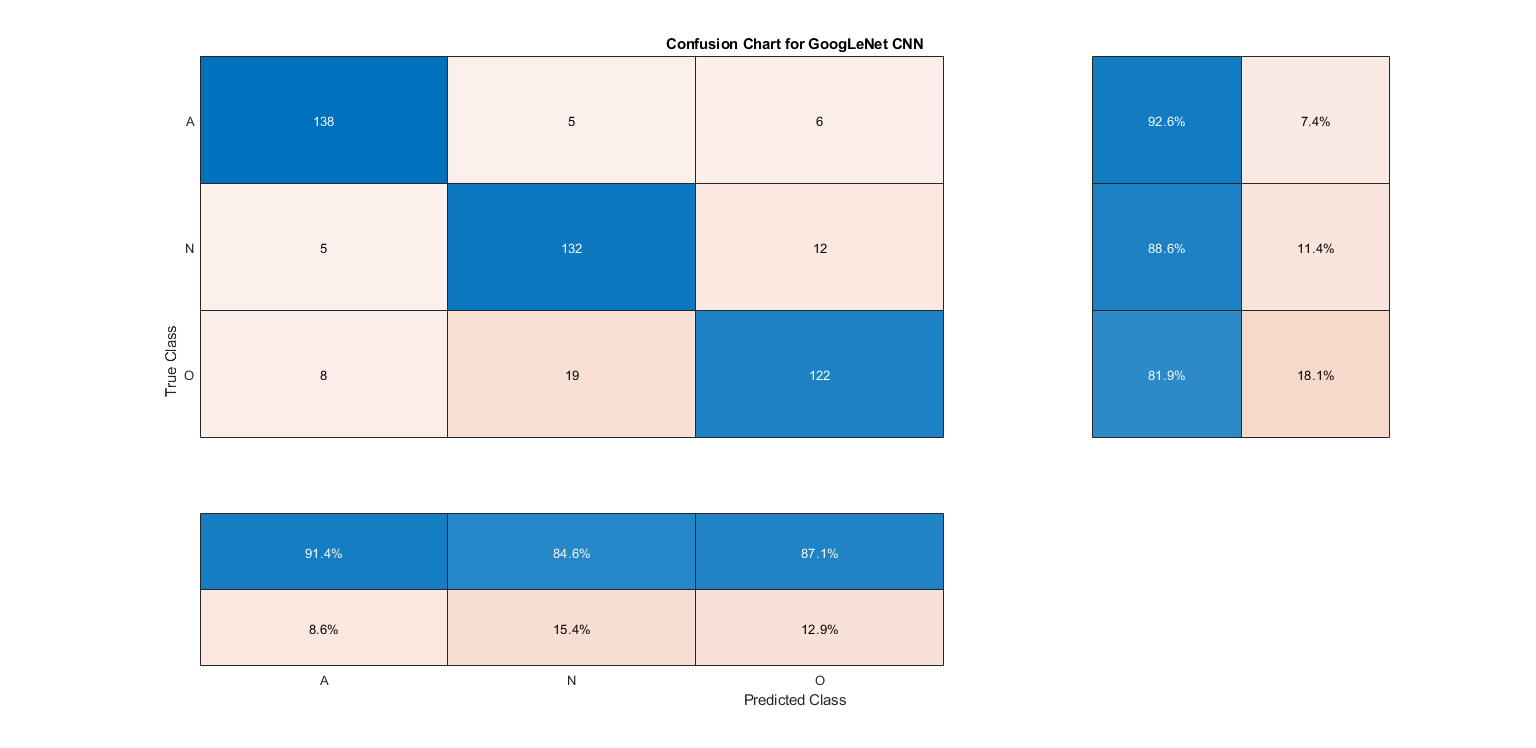

%scores
Predictions = classify(trainedGN,testing);

confusionchart(testing.Labels,Predictions,'ColumnSummary','column-normalized',...
              'RowSummary','row-normalized','Title','Confusion Chart for GoogLeNet CNN');

cfsmat = confusionmat(testing.Labels,Predictions);

acc = mean(Predictions==testing.Labels);
[p, r, f1] = predictionScoresMulti(cfsmat);
disp(['Accuracy: ', num2str(100*acc),'%']);

Accuracy: 87.6957%


disp(['Precision: ', num2str(p)]);

Precision: 0.91391


disp(['Recall: ',num2str(r)]);

Recall: 0.92617


disp(['F1 score: ', num2str(f1)]);

F1 score: 0.92


save('GoogleNet1509','trainedGN','lgraph','options');